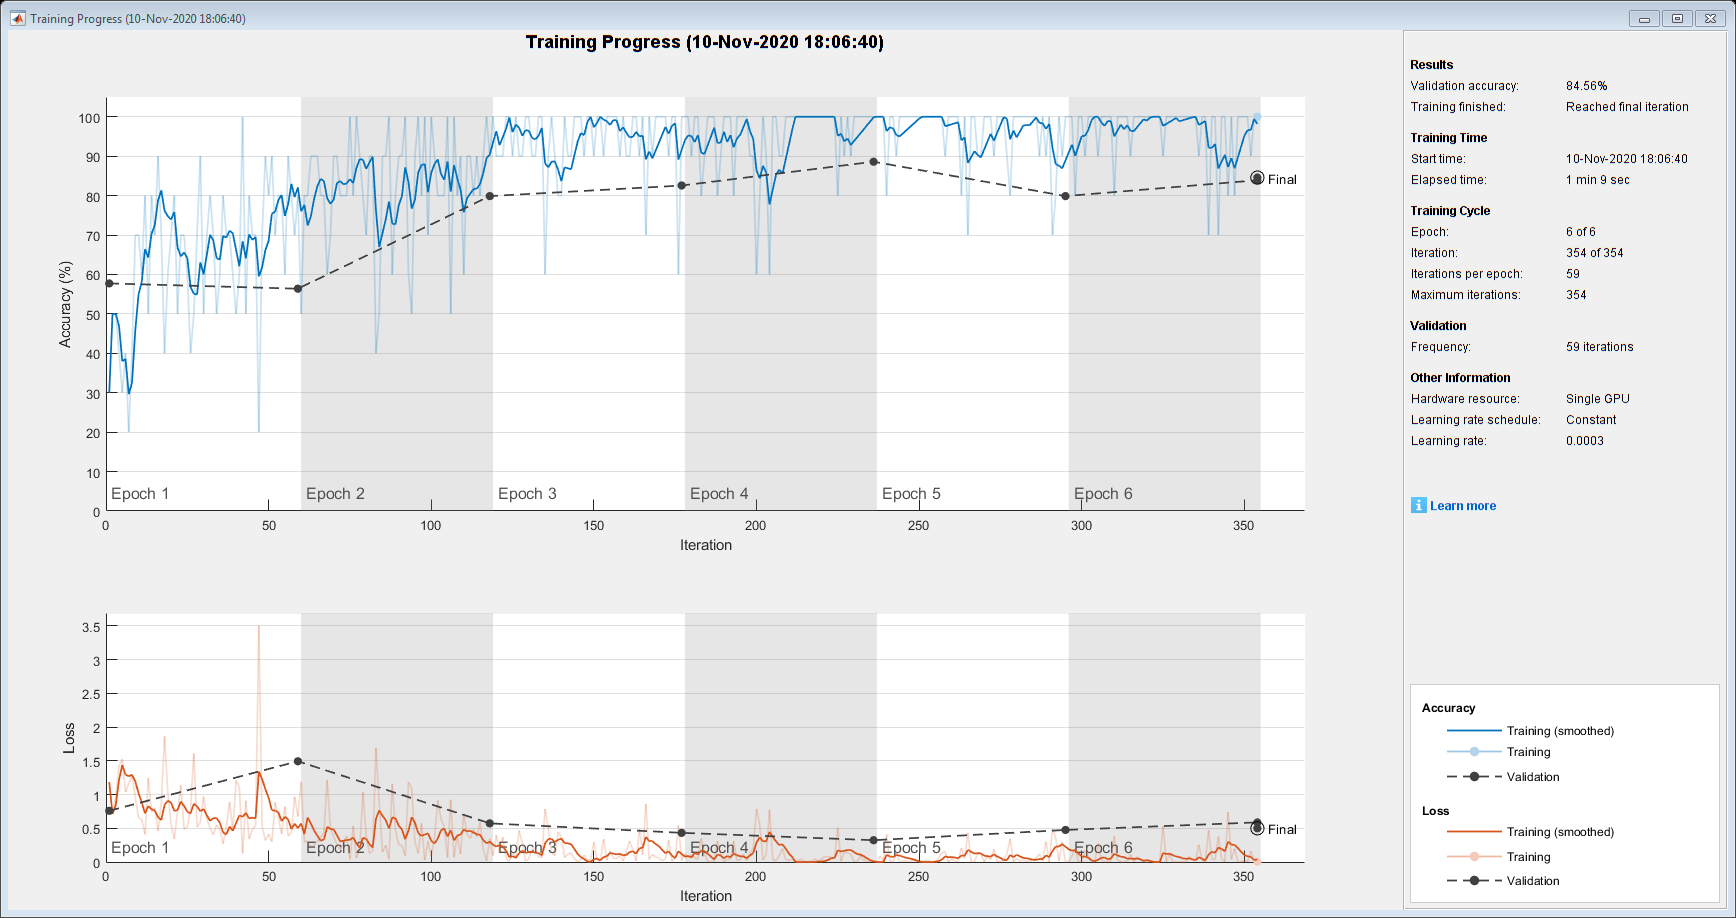

% Matlab code for classification of COVID-19 CT data
% CT Database URL: https://github.com/UCSD-AI4H/COVID-CT
% Paper title: "A Comprehensive Study on Classification of COVID-19 
% on Computed Tomography with Pretrained Convolutional Neural Networks"
% Author: Tuan Pham


clear all

% COVID = SEN = 349 
% Non-COVID = SPE = 397

% Specify your "rootFolder" (your own data folder that has 2 sub-folders for
% COVID-19 and non-COVID-19)
% See example below:
% rootFolder = 'C:\WORK\COVID-19-CT\Data'; 
rootFolder = fullfile('images_and_split', {'CT_COVID', 'CT_NonCOVID'});

% Load pretrained network

% Net 1
% net = nasnetlarge; 
% Net 2
%net = inceptionv3;
% Net 3
%net = inceptionresnetv2;
% Net 4
%net = resnet50; 
% Net 5
%net = resnet101;
% Net 6
%net = vgg16;
% Net 7
%net = densenet201;
% Net 8
%net = googlenet;
% Net 9
%net = alexnet;
% Net 10
% net = squeezenet;
% Net 11
%net = mobilenetv2;
% Net 12
net = resnet18;
% Net 13 
%net = xception;
% Net 14
%net = shufflenet;
% Net 15
%net = nasnetmobile;
% Net 16
%net = vgg19;


% Create image datastore and read labels of sub-folders
imds = imageDatastore(rootFolder, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames'); 

% Initialize results
ACC=[];
SEN=[];
SPE=[];
F1=[];

% CHANGED TO ONE RUN FOR NOW.
for i =1:1
    
% Randomly divide the data into training and validation data sets. 
% Use 80% of the images for training and 20% for validation.

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.8,'randomize');

% Display an interactive visualization of the network architecture and 
% detailed information about the network layers.

analyzeNetwork(net)

% The first element of the Layers property of the network is the image input layer.
inputSize = net.Layers(1).InputSize;

% Extract the layer graph from the trained network. 
% If the network is a SeriesNetwork object, such as AlexNet, VGG-16, or VGG-19, 
% then convert the list of layers in net.Layers to a layer graph.

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

% Find the names of the two layers to replace
 [learnableLayer,classLayer] = findLayersToReplace(lgraph);
 

% In most networks, the last layer with learnable weights is a fully connected layer. 
% Replace this fully connected layer with a new fully connected layer with the number 
% of outputs equal to the number of classes in the new data set (2, in this study). 
% In some networks, such as SqueezeNet, the last learnable layer is a 1-by-1 
% convolutional layer instead. In this case, replace the convolutional layer with a 
% new convolutional layer with the number of filters equal to the number of classes. 
% To learn faster in the new layer than in the transferred layers, 
% increase the learning rate factors of the layer.


numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);


% The classification layer specifies the output classes of the network. 
% Replace the classification layer with a new one without class labels. 
% trainNetwork automatically sets the output classes of the layer at training time. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

% Train Network

% Use an augmented image datastore to automatically resize the training images. 
% Specify additional augmentation operations to perform on the training images: 
% randomly flip the training images along the vertical axis and randomly translate them 
% up to 30 pixels and scale them up to 10% horizontally and vertically. 
% Data augmentation helps prevent the network from overfitting and memorizing 
% the exact details of the training images.  

%{
pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter, 'ColorPreprocessing','gray2rgb');
%}

augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain,...
    'ColorPreprocessing','gray2rgb'); % NO augmentation


% To automatically resize the validation images without performing further data augmentation, 
% use an augmented image datastore without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation,...
    'ColorPreprocessing','gray2rgb');


% Specify the training options

miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

% Train the network using the training data. By default, trainNetwork uses a GPU 
% if one is available (requires Parallel Computing Toolbox™ and a CUDA enabled GPU 
% with compute capability 3.0 or higher). Otherwise, trainNetwork uses a CPU.

net = trainNetwork(augimdsTrain,lgraph,options);

% Classify the validation images using the fine-tuned network, 
% and calculate the classification accuracy.

[YPred,probs] = classify(net,augimdsValidation);
% accuracy = mean(YPred == imdsValidation.Labels);


% Get the known labels
testLabels = imdsValidation.Labels;

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, YPred);

% Display the mean accuracy
accuracy = (sum(diag(confMat))/sum(sum(confMat)))*100;
sensitivity = (confMat(2,2)/(confMat(2,1)+confMat(2,2)))*100; % COVID
specificity = (confMat(1,1)/(confMat(1,1)+confMat(1,2)))*100; % NON-COVID
f1score = (2*confMat(2,2))/(2*confMat(2,2)+confMat(2,1)+confMat(1,2));

ACC=[ACC,accuracy];
SEN=[SEN,sensitivity];
SPE=[SPE,specificity];
F1 = [F1,f1score];

end 


%--------------------------
mACC = mean(ACC);
mSEN = mean(SEN);
mSPE = mean(SPE);
mF1 = mean(F1);

sACC = std(ACC);
sSEN = std(SEN);
sSPE = std(SPE);
sF1 = std(F1);

display(mACC);

mACC = 84.5638

display(mSEN);

mSEN = 75.9494

display(mSPE);

mSPE = 94.2857

display(mF1);

mF1 = 0.8392


display(sACC);

sACC = 0

display(sSEN);

sSEN = 0

display(sSPE);

sSPE = 0

display(sF1);

sF1 = 0


display(ACC);

ACC = 84.5638

display(SEN);

SEN = 75.9494

display(SPE);

SPE = 94.2857

display(F1);

F1 = 0.8392